# **LABORATORIO 1 - Análisis de las Características de un Robot Industrial y Modelo Geométrico Directo**

**Punto 5**

Se utiiza el Robotics System Toolbox, propio de MATLAB, para la creación del manipulador de KUKA, KR340 R3330. Algunos robots están precargados en la librería del *toolbox,* pero esta referencia no es uno de ellos.

testRobot = loadrobot('kukaIiwa7', 'DataFormat', 'row', 'Gravity', [0 0 -9.81])

testRobot =   rigidBodyTree with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'iiwa_link_0'  'iiwa_link_1'  'iiwa_link_2'  'iiwa_link_3'  'iiwa_link_4'  'iiwa_link_5'  'iiwa_link_6'  'iiwa_link_7'  'iiwa_link_ee'  'iiwa_link_ee_kuka'}
      BaseName: 'world'
       Gravity: [0 0 -9.8100]
    DataFormat: 'row'


config = randomConfiguration(testRobot)

config =     0.8886    0.8543    2.5653    0.7860    0.4056   -0.4991    0.8221


transform = getTransform(testRobot, config, 'iiwa_link_ee', 'iiwa_link_0')

transform =     0.7845    0.0278   -0.6195    0.6414
    0.4115   -0.7706    0.4866    0.4752
   -0.4639   -0.6367   -0.6160    0.5509
         0         0         0    1.0000


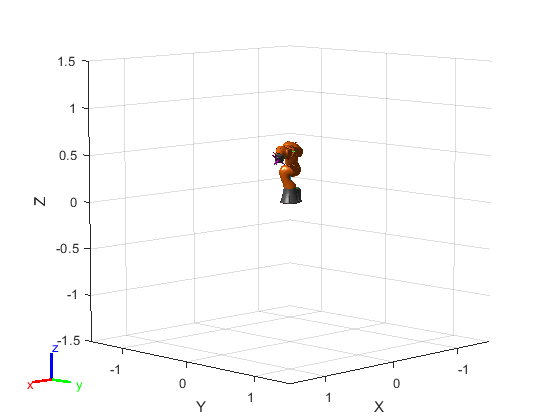

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


show(testRobot, config)

Para esto, y siguiendo la guía *Buid a Robot Step by Step*, se crea un objeto que simule el comportamiento del manipulador especificado anteriormente. Cada uno de los elementos del robot KR 340 R3330, sus 6 eslabones, su base y su efector final, deben crearse por separado para luego juntarlos por medio de las articulaciones.

#### Paso 1

Se crean los 6 eslabones de robot como elementos *rigidBody*, a cada uno se le asigna un nombre de identificación que será usado después.

body1 = rigidBody('Body1');
body2 = rigidBody('Body2');
body3 = rigidBody('Body3');
body4 = rigidBody('Body4');
body5 = rigidBody('Body5');
body6 = rigidBody('Body6');

#### Paso 2

Se crean las 6 articulaciones como elementos *rigidBodyJoint*, se les asigna un nombre de identificación y su naturaleza, para este caso, todas de tipo rotacional.

joint1 = rigidBodyJoint('Joint1', 'revolute');
joint2 = rigidBodyJoint('Joint2', 'revolute');
joint3 = rigidBodyJoint('Joint3', 'revolute');
joint4 = rigidBodyJoint('Joint4', 'revolute');
joint5 = rigidBodyJoint('Joint5', 'revolute');
joint6 = rigidBodyJoint('Joint6', 'revolute');

Se establecen sus posiciones iniciales de acuerdo sus respectivas variables de articulación.

joint1.HomePosition = 0;
joint2.HomePosition = pi/2;
joint3.HomePosition = 0;
joint4.HomePosition = 0;
joint5.HomePosition = 0;
joint6.HomePosition = 0;

Se establecen las diferentes matrices de transformación homogéneas correspondientes a las configuraciones de los marcos de referencia de los eslabones con respecto al cuerpo inmediatamente anterior. Los valores empleados, en milímetros, se extraen de la hoja técnica del manipulador.

transform1 = trvec2tform([0 0 1045])

transform1 =            1           0           0           0
           0           1           0           0
           0           0           1        1045
           0           0           0           1


transform2 = trvec2tform([500 0 0])*eul2tform([pi/2 -pi/2 0])

transform2 =     0.0000   -1.0000   -0.0000  500.0000
    0.0000    0.0000   -1.0000         0
    1.0000         0    0.0000         0
         0         0         0    1.0000


transform3 = trvec2tform([1300 0 0])

transform3 =            1           0           0        1300
           0           1           0           0
           0           0           1           0
           0           0           0           1


transform4 = trvec2tform([-55 -1525 0])*eul2tform([-pi/2 pi/2 pi/2])

transform4 = 	1.0e+03 *

    0.0000    0.0000   -0.0010   -0.0550
   -0.0000   -0.0010   -0.0000   -1.5250
   -0.0010    0.0000    0.0000         0
         0         0         0    0.0010


transform5 = trvec2tform([0 0 0])*eul2tform([-pi/2 -pi/2 pi/2])

transform5 =     0.0000         0   -1.0000         0
   -0.0000    1.0000         0         0
    1.0000    0.0000    0.0000         0
         0         0         0    1.0000


transform6 = trvec2tform([0 0 0])*eul2tform([-pi/2 pi/2 pi/2])

transform6 =     0.0000    0.0000   -1.0000         0
   -0.0000   -1.0000   -0.0000         0
   -1.0000    0.0000    0.0000         0
         0         0         0    1.0000


Cada una de estas MTH se asignan a su correspondiente articulación.

setFixedTransform(joint1, transform1)
setFixedTransform(joint2, transform2)
setFixedTransform(joint3, transform3)
setFixedTransform(joint4, transform4)
setFixedTransform(joint5, transform5)
setFixedTransform(joint6, transform6)

Se asocian cada uno de los eslabones con su correspondiente articulación.

body1.Joint = joint1;
body2.Joint = joint2;
body3.Joint = joint3;
body4.Joint = joint4;
body5.Joint = joint5;
body6.Joint = joint6;

#### Paso 3

Se crea un nuevo elemento tipo *rigidBodyTree* que representa todo el conjunto del manipulador.

robotKUKA = rigidBodyTree;

#### Paso 4

Se relacionan cada uno de los eslabones con su cuerpo "padre", para establecer las dependencias adecuadas en la cadena cinemática.

addBody(robotKUKA, body1, 'base')
addBody(robotKUKA, body2, 'Body1')
addBody(robotKUKA, body3, 'Body2')
addBody(robotKUKA, body4, 'Body3')
addBody(robotKUKA, body5, 'Body4')
addBody(robotKUKA, body6, 'Body5')

#### Paso 5

Ahora, se hace un procedimiento similar de creación de nuevos objetos pero esta vez con el efector final. Su principal característica es que será agragado atado al eslabón 6.

bodyEndEffector = rigidBody('EndEffector');
transform7 = trvec2tform([0 0 290])

transform7 =      1     0     0     0
     0     1     0     0
     0     0     1   290
     0     0     0     1


setFixedTransform(bodyEndEffector.Joint, transform7)
addBody(robotKUKA, bodyEndEffector, 'Body6')

#### Paso 6

Finalmente, se hace un resumen de los detalles del robot creado.

showdetails(robotKUKA)

--------------------
Robot: (7 bodies)

 Idx          Body Name             Joint Name             Joint Type          Parent Name(Idx)   Children Name(s)
 ---          ---------             ----------             ----------          ----------------   ----------------
   1              Body1                 Joint1               revolute                   base(0)   Body2(2)  
   2              Body2                 Joint2               revolute                  Body1(1)   Body3(3)  
   3              Body3                 Joint3               revolute                  Body2(2)   Body4(4)  
   4              Body4                 Joint4               revolute                  Body3(3)   Body5(5)  
   5              Body5                 Joint5               revolute                  Body4(4)   Body6(6)  
   6              Body6                 Joint6               revolute                  Body5(5)   EndEffector(7)  
   7        EndEffector        EndEffector_jnt                  fixed 

Además, se hace una gráfica del modelo en su posición de *home*.

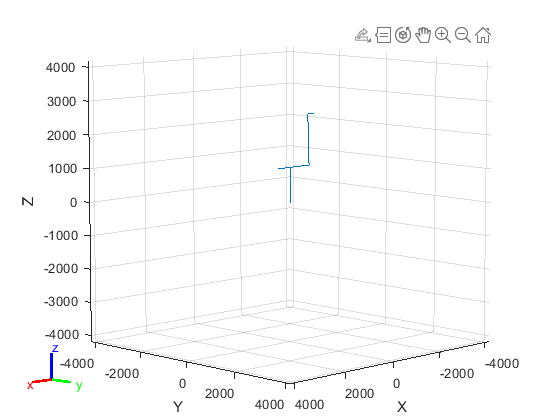

ans =   Axes (Primary) with properties:

             XLim: [-4.1785e+03 4.1785e+03]
             YLim: [-4.1785e+03 4.1785e+03]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


show(robotKUKA, homeConfiguration(robotKUKA))